clear; close all;

% Demo dynamics
N = 25;
% State space
A = [0.8, 0.1, 0.2; 0.2, 0.7, 0.15; 0.1, -0.05, 0.6];
B = [0.1, 0.15; 0.05, 0.1; 1, 0.4];
C = [1, 0, 0; 0, 1, 0];
% Lifted form
P = mimo_lifted_dynamics(A, B, C, N);


% Reference
ur = randn(N*2,1);
r  = P*ur;

% Setup IO-MOLE
dyn_func = @(u)run_linear_mimo_ss_dynamics(A, B, C, zeros(3,1), u);
mimo_mole = CMIMOMOLE(dyn_func, 2, 3, C);

% Initial input trajectory
u0 = 0.01*randn(N*2, 1);

% Number of trials
J = 15;

% Run IO-MOLE
tic;
[ev, ec, yc, uc] = mimo_mole.run_mimo_mole(r, u0, J);
toc;

Elapsed time is 5.231014 seconds.


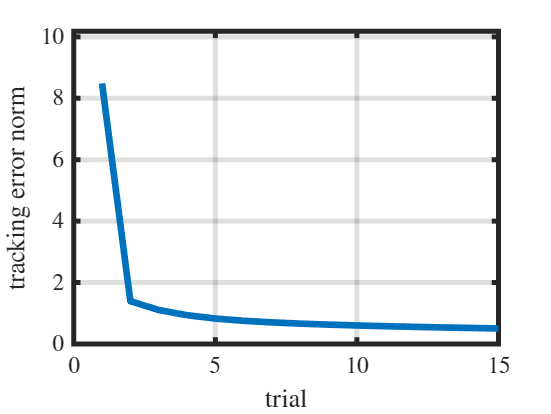


% Plot error norms
figure;
plot(ev);
xlabel('trial');
ylabel('tracking error norm');
ylim([0, ev(1)*1.2]);

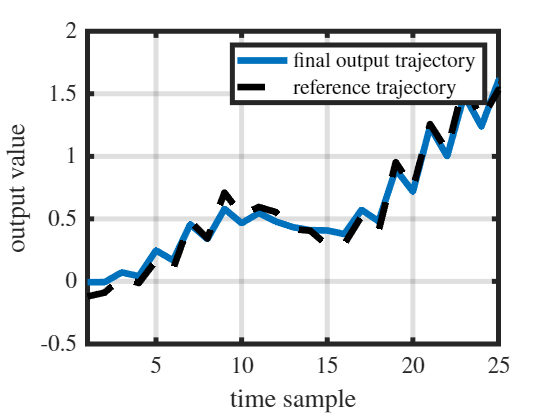


% Plot reference and final output trajectory
figure;
plot(yc{end,1}); hold on;
plot(r, '--', 'Color', 'black');
xlabel('time sample');
ylabel('output value');
legend('final output trajectory', 'reference trajectory');
xlim([1,N]);